clear
load zipdata.mat

% azip -> Training data
% dzip -> Result for training data
% testzip -> Test data
% dtest -> Result for test data

% Assignment: Implement the tangent distance classifier

% Att göra: 
% Blurra bilderna för bättre resultat
% För att ta bort de gråa områderna/bakgrunderna


test = azip(:,:,1)

test =          0         0         0         0         0         0         0    0.1845    0.9310    0.4165         0         0         0         0         0         0
         0         0         0         0         0         0    0.0040    0.6485    1.0000    0.6535         0         0         0         0         0         0
         0         0         0         0         0         0    0.2950    1.0000    0.9930    0.2175         0         0         0         0         0         0
         0         0         0         0         0    0.1585    0.9125    1.0000    0.7810         0         0         0         0         0         0         0
         0         0         0         0    0.0310    0.7700    1.0000    0.8890    0.1425         0         0         0         0         0         0         0
         0         0         0         0    0.5500    1.0000    0.9610    0.2805         0         0         0         0         0         0         0         0
         0         0       

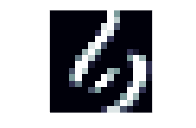


% Padding white border around to be able to calculate the corners and edges
padding = zeros(16,1);
test = cat(1,test,padding');
padding = zeros(17,1);
test = cat(2,test, padding);
test = cat(2,padding, test);
padding = zeros(18,1);
test = cat(1, padding', test);

xdiv = zeros(16);
ydiv = zeros(16);

for i = 2:17 % rad
    for j = 2:17 % column
        ydiv(i-1,j-1) = (test(i+1,j) - test(i-1,j))/2; 
        xdiv(i-1,j-1) = (test(i,j+1) - test(i,j-1))/2;
    end
end

ima(xdiv)
ima(ydiv)

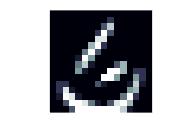


ima(azip(:,:,1))

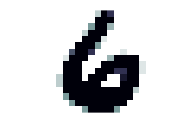


% Translation 
ima(test(2:17,2:17)-xdiv*0.3) % Det är 0.3 vi ska räkna ut sen som tangent med minsta kvadrat problem

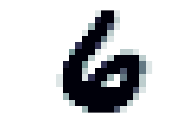

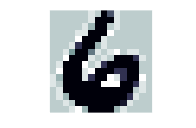


% Tjockare/tunnare
ima(test(2:17, 2:17) - (xdiv.*xdiv + ydiv.*ydiv)*0.5)


% Rotation

for i = 2:17
    for j = 2:17
        
    end
end
